# Practice 1: Energy Expenditure and Smartphones

This is a [matlab function](https://it.mathworks.com/help/matlab/matlab_prog/create-functions-in-files.html), sought for computing **E**nergy **E**xpenditure from processed, acceleration data according to ***lecture 1-3***. Remember to download the entire folder **Practice_1-EnergyExpenditure**, and store it either locally in your computer or in your [Matlab Drive](https://drive.matlab.com/).  In the later case, after you uploaded the material to your Matlab Drive, matlab functions and scripts can be written and launched directly in [Matlab Online](https://it.mathworks.com/products/matlab-online.html).

In the first part of the Exam students had to write a function to compute ${\textrm{IAA}}_{\textrm{tot}}$, corresponding to the integral of absolute acceleration data summed over the three axes.  In this second part students must convert these ${\textrm{IAA}}_{\textrm{tot}}$ values into estimates of energy expenditure ($\textrm{EE}$) in kcal unit.

$\textrm{EE}$ must be computed using the relationship reported by Bouten and colleagues (1998):

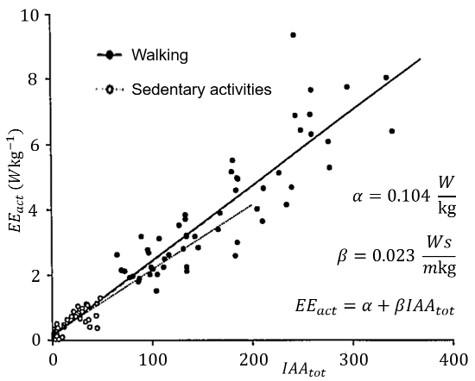

Please, note the relationship just illustrated converts acceleration data (`IAAtot`) to **relative power** `EE_act`.  Students are therefore requested to convert **relative power** into **absolute work** (`EE`) in kcal units according to the steps illustrated below and in class.

## How should students complete this Matlab function?

Complete the code below to compute the **E**nergy **E**xpenditure (`EE`) from processed acceleration data (`IAAtot`).  This implies:

- using the coefficients of the first-order polynomal model to obtain relative power (`EE_act`)

- compute the accumulated, relative work (`EE_w`)

- account for the individual body mass to obtain **E**nergy **E**xpenditure (`EE`)

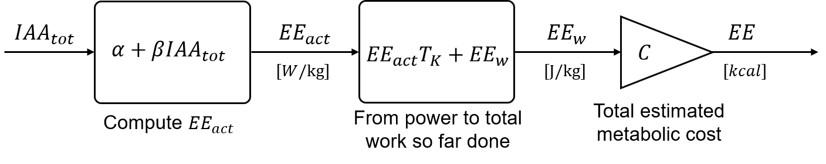

The code is to be run as a [matlab function](https://it.mathworks.com/help/matlab/matlab_prog/create-functions-in-files.html), taking three input arguments and providing user with a scalar:

### Input arguments

- `IAAtot`: single element variable, containing the sum of the integrated, absolute, acceleration values (cf. below and ***lecture 1-3***).

- `body_mass`: single element variable, containing the total mass (kg) of the subject wearing the smartphone.

- `EE_passed_in`: optional, single element variable.  This should correspond to the `EE` value computed for the previous call to the function.  When this third argument is not passed in to the function, a persistent variable `EE_w` is used.

### Output arguments

- `EE`: single element variable, containing the accumulated work done so far (cf. below and ***lecture 1-3***).

## The code - matlab function

The code is partly completed, with the sole aim of providing students with one of many possible solutions.

Start using the standard definition statement for creating matlab functions.  Two possible implementations are to be pursued here, according to the number of input arguments provided to the function (third agrument is optional).

function EE = fromIaaTotToEnergyExpenditure(IAA_tot,body_mass,EE_passed_in)

### Definition of parameters

Three main parameters to be defined here are the coefficients of the first-order, polynomial model, $\alpha \;$(`alpha`) and $\beta$ (`beta`), and the duration $T_k$ (`T_k`) for converting **relative power** (`EE_act`) to **relative work **(`EE_w`).  These parameters are defined as [persistent](https://it.mathworks.com/help/matlab/ref/persistent.html) variables, [saving the need](https://it.mathworks.com/matlabcentral/answers/254121-does-persistent-variable-help-speed) to recompute them across function invocations.

Two out of many possible implementations are encouraged to be tested here, impacting on the need of using:

- the persistent `EE_w` variable is declared, to be used only if two, input arguments are passed to the function

- or the third argument `EE_passed_in` to the function

% declaring persistent variables (their value is preserved between function calls)
persistent T_k alpha beta EE_w

if isempty(T_k) % if this is the first time this function is invoked
    alpha = 0.104; % intercept Bouten regression equation
    beta = 0.023; % slope Bouten regression equation
    T_k = 30; % duration over which acceleration data (IAAtot) has been integrated
    EE_w = 0; % relative work
end

### Processing IAAtot value

Relative power is to be computed according to the relationship:


$${\textrm{EE}}_{\textrm{act}} =\alpha +\beta \;{\textrm{IAA}}_{\textrm{tot}}$$


% code here
EE_act = IAA_tot*beta+alpha; % converting integrated, acceleration data to relative power (W/kg)

### Converting relative power to work

The relative power just computed is to be converted into accumulated, relative work (`EE_w`).  Accumulated means the relative work is to be summed cumulatively with preceeding, relative work values as per the scheme above.

Accumulated, relative work may be computed considering either the persistent variable declared above (`EE_w`) or the third input argument (`EE_passed_in`).  In the later case, remember to convert it back to `EE_w`.  The [nargin](https://it.mathworks.com/help/matlab/ref/nargin.html) function may be used to test for the number of input arguments.

% code here
% from W/kg to J/kg
if nargin == 2
    % use the persistent variable to retrieve previous, relative work value
else
    % use the third input argument to retrieve previous, relative work value
end

### Computing Energy Expenditure

The only point left is to convert to kcal unit and to account for the individual, body mass.

% code here